# GUI & Algorithm

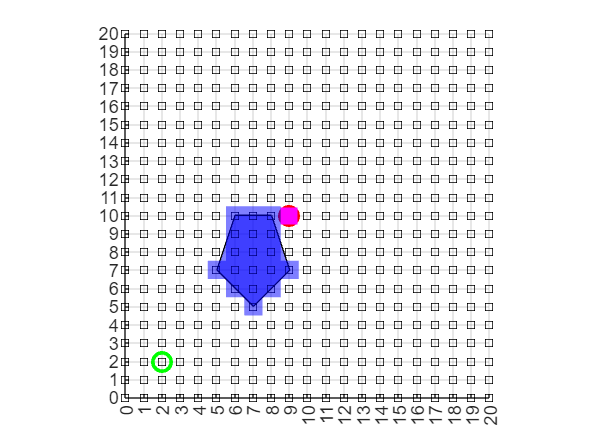

Matrix A:


   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   

Final point (grasp point) value in A: -2


A =    Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf     1   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf   In

% Define the size of the grid
gridSize = 20;


% Create the figure and axes
figure;
hold on;
axis equal;
grid on;
set(gca, 'XTick', 0:gridSize, 'YTick', 0:gridSize); % Adjust grid size as needed
xlim([0 gridSize]);
ylim([0 gridSize]);
set(gca, 'YDir', 'reverse'); % Reverse the Y-axis direction

% Define the start point
xi = 2;
yi = 2;

% Plot start point
plot(xi, yi, 'go', 'MarkerSize', 10, 'LineWidth', 2);

% Define the object's vertices (pentagon)
object_vertices_x = [7, 9, 8, 6, 5];
object_vertices_y = [5, 7, 10, 10, 7];

% Create the object shape
fill(object_vertices_x, object_vertices_y, 'b', 'FaceAlpha', 0.5);

% Define grasp point on the object (let's use the top vertex for this example)
% An error occurs if:
% xf = 8;
% yf = 10;

% The function will activate if:
xf = 9;
yf = 10;

% Check if the grasp point is within the object zone
in_object = inpolygon(xf, yf, object_vertices_x, object_vertices_y);

if in_object
    disp('ERROR: The final point is within the object zone.');
else
    % Plot final point (grasp point)
    plot(xf, yf, 'ro', 'MarkerSize', 10, 'LineWidth', 2);

    % Display grid
    for i = 0:gridSize
        for j = 0:gridSize
            plot(i, j, 'ks', 'MarkerSize', 5, 'MarkerFaceColor', 'none');
        end
    end

    % Highlight the grasp point on the object
    plot(xf, yf, 'ms', 'MarkerSize', 10, 'LineWidth', 2, 'MarkerFaceColor', 'magenta');

    % Create a polygon from the object's vertices
    [xq, yq] = meshgrid(0:gridSize, 0:gridSize);
    in = inpolygon(xq, yq, object_vertices_x, object_vertices_y);

    % Create matrix A representing the 2D space
    A = inf(gridSize + 1, gridSize + 1); % Initialize with inf values

    % Mark the start point in A
    A(yi + 1, xi + 1) = 0; % Starting point set to 0

    % Highlight the cells inside the polygon and update the matrix A
    for i = 1:numel(xq)
        if in(i)
            A(yq(i) + 1, xq(i) + 1) = -1; % Using -1 to represent the object
            fill(xq(i) + [-0.5 0.5 0.5 -0.5], yq(i) + [-0.5 -0.5 0.5 0.5], 'b', 'FaceAlpha', 0.5, 'EdgeColor', 'none');
        end
    end

    % Mark the grasp point in A
    A(yf + 1, xf + 1) = -2;

    hold off;

    % Print the matrix A to the screen
    disp('Matrix A:');
    disp(A);

    % Display the final point (grasp point) in the matrix A
    final_point_value = A(yf + 1, xf + 1);
    disp(['Final point (grasp point) value in A: ', num2str(final_point_value)]);

    % Algorithm
    unvisit = [];
    visit = [];
    visit = [visit; [xi, yi]];

    % Updating Unvisit list
    unvisit = [unvisit; [xi + 1, yi]; [xi - 1, yi]; [xi, yi + 1]; [xi, yi - 1]];

    % Edit matrix values
    A(yi + 1, xi + 1) = 0; % Start point
    A(yi + 1 + 1, xi + 1) = 1;
    A(yi + 1 - 1, xi + 1) = 1;
    A(yi + 1, xi + 1 + 1) = 1;
    A(yi + 1, xi + 1 - 1) = 1;

    % Updating Visit list
    if (A(yi + 1 + 1, xi + 1) <= A(yi + 1 - 1, xi + 1)) && (A(yi + 1 + 1, xi + 1) <= A(yi + 1, xi + 1 + 1)) && (A(yi + 1 + 1, xi + 1) <= A(yi + 1, xi + 1 - 1))
        visit = [visit; [xi + 1, yi]];
    elseif (A(yi + 1 - 1, xi + 1) <= A(yi + 1 + 1, xi + 1)) && (A(yi + 1 - 1, xi + 1) <= A(yi + 1, xi + 1 + 1)) && (A(yi + 1 - 1, xi + 1) <= A(yi + 1, xi + 1 - 1))
        visit = [visit; [xi - 1, yi]];
    elseif (A(yi + 1, xi + 1 + 1) <= A(yi + 1 - 1, xi + 1)) && (A(yi + 1, xi + 1 + 1) <= A(yi + 1 + 1, xi + 1)) && (A(yi + 1, xi + 1 + 1) <= A(yi + 1, xi + 1 - 1))
        visit = [visit; [xi, yi + 1]];
    else
        visit = [visit; [xi, yi - 1]];
    end

    % Updating unvisit list
    last = visit(end, :);
    x = last(1);
    y = last(2);
    unvisit = [unvisit; [x + 1, y]; [x - 1, y]; [x, y + 1]; [x, y - 1]];
    edit_value = [[x + 1, y]; [x - 1, y]; [x, y + 1]; [x, y - 1]];

    % Removing visited vertices from unvisit list
    who_is = ismember(unvisit, visit, "rows");
    count_unvisit = 0;
    for i = 1:length(unvisit)
        if who_is(i) == 1
            unvisit(i - count_unvisit, :) = [];
            count_unvisit = count_unvisit + 1;
        end
    end

    who_is = ismember(edit_value, visit, "rows");
    count_edit_value = 0;
    for i = 1:length(edit_value)
        if who_is(i) == 1
            edit_value(i - count_edit_value, :) = [];
            count_edit_value = count_edit_value + 1;
        end
    end

    % Updating matrix value
    for i = 1:length(edit_value)
        x_local = edit_value(i, 1);
        y_local = edit_value(i, 2);
        A(y_local + 1, x_local + 1) = A(y + 1, x + 1) + 1;
    end
end

